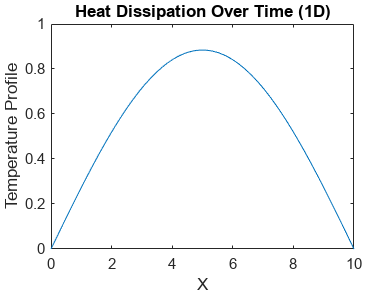

M1D =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0              

format long;
close all;
clf;

% 1-D example input
IC1D = @(x, l)    sin(x*pi/l);
h = 0.01;
k = 0.0001;
x_lim = 10;
alpha = 0.5;
t = 5;
N = (x_lim./h)+1;

% 2-D example input
IC2D = @(x, x_lim, y, y_lim)    sin(x.*pi./x_lim).*sin((y.*pi)./y_lim);
h2 = 0.1;
z = 0.1;
k2 = 0.00005;
x_lim2 = 5;
N2 = (x_lim2./h2)+1;
alpha2 = 1;
t2 = 1;
y_lim = 5;

M1D = FD_1D (IC1D, N, h, k, x_lim, alpha, t)

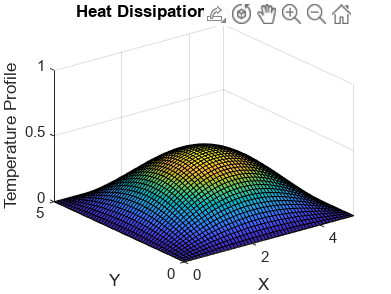

M2D = M2D(:,:,1) =

                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0

M2D = FD_2D(IC2D, N2, h2, k2, z, x_lim2, alpha2, t2, y_lim)

function M = FD_1D (f, N, h, k, x_lim, alpha, t)
% 1-D implementation 
M = zeros(N,t/k);
x = 0:h:x_lim;
M(:, 1) = (f(x, x_lim))';
pause (0.1)

% Populate 2-D matrix
for j = 1:t/k-1
    for i = 2: N-1
        % Update formula
        M(i, j+1) = ((1- ((2*(alpha.^2)*k)./h.^2))).*M(i, j)+ (alpha.^2)* (k./h.^2)* (M(i+1, j) + M(i-1, j));
    end
end

% Animation code
for i = 1:100:t/k
    plot (x, M(:, i));
    axis([0 x_lim 0 1])
    xlabel('X')
    ylabel('Temperature Profile')
    title('Heat Dissipation Over Time (1D)')
    pause(0.01)
end
end

function M = FD_2D(f, N, h, k, z, x_lim, alpha, t, y_lim)
% 2-D implementation
M = zeros(x_lim/h+1, y_lim/z+1, t/k+1);
x = 0:h:x_lim;
y = 0:z:y_lim;
[X, Y] = meshgrid(x, y);
M(:,:, 1) = (f(X, x_lim, Y , y_lim))';

% Storing coefficients for readability
c1 = (((alpha.^2).*k)./(h.^2));
c2 = (((alpha.^2).*k)./(z.^2));
pause (0.1)

% Traversal for t
for e = 1:t/k
    % Traversal for x
    for i = 2: x_lim/h
        % Traversal for y
        for j = 2:y_lim/z
            % Update formula
          M(i, j, e+1) = (c1.*(M(i+1,j,e)-2.*(M(i,j,e)) + M(i-1,j,e))) + (c2*(M(i,j+1,e)-2.*M(i,j,e) + M(i,j-1,e))) + M(i,j,e);
        end
    end
end

% Animation code
for i = 1:100:t/k
    surf(x, y, M(:,:, i));
    axis([0 x_lim 0 y_lim 0 1])
    xlabel('X')
    ylabel('Y')
    zlabel('Temperature Profile')
    title('Heat Dissipation Over Time (2D)')
    pause(0.01)
end
end